## Relativity The Special and General Theory 

일반 상대성 이론은 아인슈타인이 1916년에 발표한 이론으로, **중력**을 설명하는 이론입니다. 특수 상대성 이론이 중력과 가속도가 없는 상황에서만 적용된다는 한계를 극복하기 위해, 아인슈타인은 중력을 **시공간의 휘어짐**으로 해석하였습니다.

**핵심 개념:**

- **등가 원리 (Principle of Equivalence)**:

- 가속도와 중력은 본질적으로 구별할 수 없다는 원리입니다. 즉, 가속도에 의해 발생하는 힘과 중력에 의한 힘은 동일하게 작용합니다.

- 예를 들어, 우주선 내부에서 사람이 가속도에 의해 바닥에 눌리게 되는 현상은 중력에 의한 작용과 동일하게 느껴집니다.

**시공간의 휘어짐 (Curvature of Spacetime)**:

- 중력은 물체가 시공간을 휘게 만드는 효과로 설명됩니다. 즉, 질량을 가진 물체가 시공간을 왜곡시키고, 다른 물체는 이 왜곡된 시공간을 따라 움직이게 됩니다.

- 이는 뉴턴의 고전적인 "힘으로서의 중력"과는 완전히 다른 관점입니다. 물체는 곧장 직진하려 하지만, 시공간이 휘어져 있기 때문에 곡선 경로를 따라가게 됩니다.

**아인슈타인 방정식**:

- 일반 상대성 이론은 아인슈타인 방정식으로 표현됩니다. 이 방정식은 질량과 에너지가 시공간의 휘어짐을 어떻게 만드는지를 설명합니다: 

$G_{\mu\nu} = \frac{8\pi G}{c^4} T_{\mu\nu}$�

- 여기서 $G_{\mu\nu}$는 시공간의 곡률(휘어짐)을 나타내는 아인슈타인 텐서이고, $T_{\mu\nu}$는 에너지-운동량 텐서입니다.

**주요 결과:**

- **중력에 의한 시간 지연**:

- 중력이 강한 곳에서는 시간이 더 느리게 흐릅니다. 예를 들어, 지구 표면에서는 시간의 흐름이 고도 높은 곳보다 느립니다. 이는 GPS 위성의 시간 보정에서 매우 중요한 요소입니다.

- 이 현상은 **중력 시간 지연**이라고 불리며, 아인슈타인 방정식으로 설명됩니다.

- **중력 렌즈 효과 (Gravitational Lensing)**:

- 강한 중력장은 빛의 경로를 휘게 만듭니다. 이는 마치 렌즈가 빛을 굴절시키는 것과 같은 효과를 나타내며, 우리가 멀리 있는 별이나 은하를 관찰할 때 빛이 휘어져 보이는 현상을 설명할 수 있습니다.

- **블랙홀**:

- 매우 큰 질량을 가진 물체가 시공간을 극도로 휘게 만들어, 그 안으로 빠져나올 수 없는 **블랙홀**이 형성됩니다. 이 블랙홀의 사건의 지평선(event horizon)은 그 경계를 넘은 물체나 빛이 빠져나올 수 없는 경계를 나타냅니다.

- **우주의 팽창**:

- 아인슈타인의 일반 상대성 이론은 우주의 팽창을 설명하는 데에도 중요한 역할을 합니다. 우주는 시공간 자체가 팽창하는 것이며, 이는 **빅뱅 이론**과 밀접한 관련이 있습니다.

**일반 상대성 이론의 적용:**

일반 상대성 이론은 **중력과 가속도**가 있는 상황을 설명합니다. 대규모 천체의 운동, 중력파, 블랙홀, 우주의 팽창 등에서 이 이론이 중요한 역할을 합니다.

**1. 중력 렌즈 효과 (Gravitational Lensing)**

중력 렌즈 효과는 질량이 큰 천체(예: 은하, 블랙홀)가 시공간을 휘게 하여 빛의 경로를 굴절시키는 현상입니다. 

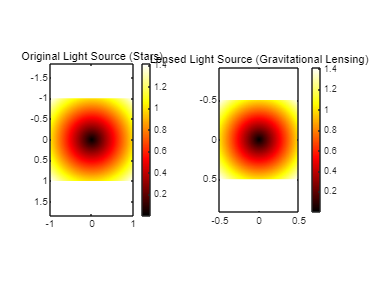

% Gravitational Lensing Visualization in MATLAB

% Define grid for the background stars (light sources)
[x, y] = meshgrid(linspace(-1, 1, 500), linspace(-1, 1, 500));

% Gravitational lens: a large mass at the center
% Define the mass of the lens (approximated as a point mass)
M = 1;  % Normalized mass
R = sqrt(x.^2 + y.^2);  % Distance from the center

% Define deflection caused by the gravitational lens
% Deflection angle is inversely proportional to the distance from the mass
deflection_x = -x ./ R.^2;
deflection_y = -y ./ R.^2;

% Prevent division by zero at the center
deflection_x(R == 0) = 0;
deflection_y(R == 0) = 0;

% Apply deflection to the grid
lens_x = x + deflection_x * M;
lens_y = y + deflection_y * M;

% Plot the original and lensed grid
figure;
subplot(1, 2, 1);
imagesc(x(1, :), y(:, 1), R);  % Original star field
title('Original Light Source (Stars)');
axis equal;
colormap('hot');
colorbar;

subplot(1, 2, 2);
imagesc(lens_x(1, :), lens_y(:, 1), R);  % Lensed star field
title('Lensed Light Source (Gravitational Lensing)');
axis equal;
colormap('hot');
colorbar;

- 중심에 큰 질량을 가진 은하가 있다고 가정하고, 이 은하의 중력에 의해 배경에서 오는 빛이 휘어지는 효과를 시각화합니다.

- 실제로 이런 현상은 빛의 경로를 구부리며, 배경에 있는 천체(예: 은하)가 여러 개의 이미지로 보이거나, 빛이 고리 모양으로 휘어져 보이는 현상이 발생할 수 있습니다. 이를 **아인슈타인 링**이라고도 합니다.

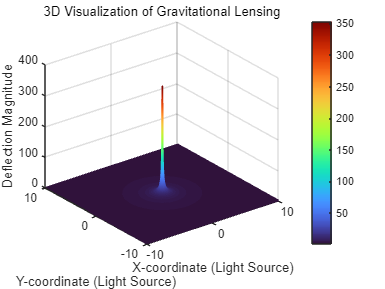

% Gravitational Lensing 3D Visualization in MATLAB

% Define grid for the background stars (light sources)
[x, y] = meshgrid(linspace(-10, 10, 500), linspace(-10, 10, 500));

% Gravitational lens: a large mass at the center
% Define the mass of the lens (approximated as a point mass)
M = 10;  % Normalized mass (larger value means stronger gravitational effect)
R = sqrt(x.^2 + y.^2);  % Distance from the center

% Define deflection caused by the gravitational lens
% Deflection angle is inversely proportional to the distance from the mass
deflection_x = -M * x ./ R.^2;
deflection_y = -M * y ./ R.^2;

% Prevent division by zero at the center
deflection_x(R == 0) = 0;
deflection_y(R == 0) = 0;

% Apply deflection to the grid
lens_x = x + deflection_x;
lens_y = y + deflection_y;

% Create a 3D plot of the deflected light paths (z = deflection)
figure;
mesh(x, y, sqrt(deflection_x.^2 + deflection_y.^2));
xlabel('X-coordinate (Light Source)');
ylabel('Y-coordinate (Light Source)');
zlabel('Deflection Magnitude');
title('3D Visualization of Gravitational Lensing');
colormap('turbo');
shading interp;
colorbar;
grid on;

- **좌표계 설정**: 중력 렌즈 효과를 시각화하기 위해 $x$와 $y$좌표계에서 은하와 배경 별(광원)의 위치를 설정합니다.

- **중력 렌즈 질량 설정**: 은하의 질량을 $M$으로 설정합니다. 큰 질량일수록 중력 렌즈 효과가 강해집니다.

- **휘어짐 계산**: 빛이 중심 질량에 의해 어떻게 굴절되는지 계산합니다. 빛의 경로가 중심에서 멀어질수록 굴절 정도가 작아지며, 중력 렌즈 효과는 $1 / R^2$에 비례하여 발생합니다.

**2. ****시공간의 휘어짐 (Spacetime Curvature)**

**시공간의 휘어짐 (Spacetime Curvature)**은 아인슈타인의 일반 상대성 이론에서 중력이 시공간을 휘게 만들며, 물체가 그 곡률에 따라 운동하게 된다는 개념입니다. 이를 시각화하기 위해, 큰 질량을 가진 물체 주변에서 시공간이 어떻게 휘어지는지 나타낼 수 있습니다. 예를 들어, 블랙홀 주변의 시공간이 휘어지는 모습을 그래프로 표현할 수 있습니다.

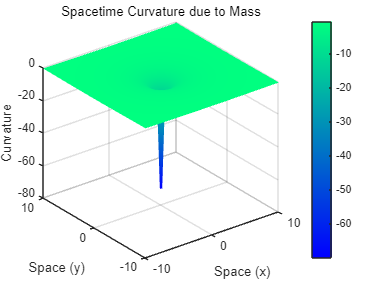

% Spacetime Curvature Visualization in MATLAB

% Define grid for spacetime (representing a 2D slice of spacetime)
[x, y] = meshgrid(linspace(-10, 10, 100), linspace(-10, 10, 100));

% Define mass that creates curvature in spacetime
M = 10;  % Mass value (larger values create more curvature)

% Calculate the gravitational potential (simplified model)
R = sqrt(x.^2 + y.^2);  % Distance from the center
curvature = M ./ (R + 1e-5);  % Simplified curvature (avoid division by zero)

% Plot the spacetime curvature as a surface
figure;
surf(x, y, -curvature, 'EdgeColor', 'none');
xlabel('Space (x)');
ylabel('Space (y)');
zlabel('Curvature');
title('Spacetime Curvature due to Mass');
colormap('winter');
shading interp;
colorbar;

- 큰 질량을 가진 물체(예: 태양, 블랙홀)가 시공간을 휘게 만드는 현상을 시각화할 수 있습니다. 이 물체 주변에서 시공간은 더 크게 휘어지며, 휘어짐은 질량에 비례하게 커집니다.

- 물체가 있는 중심에 가까울수록 시공간의 휘어짐이 더 크며, 먼 거리에서는 휘어짐이 작아집니다.

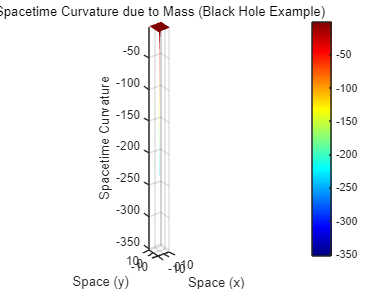

% Spacetime Curvature Visualization in MATLAB

% Define grid for spacetime (representing a 2D slice of spacetime)
[x, y] = meshgrid(linspace(-10, 10, 500), linspace(-10, 10, 500));

% Define mass that creates curvature in spacetime (e.g., a black hole or star)
M = 10;  % Normalized mass value (the larger the value, the stronger the curvature)

% Calculate the radial distance from the center (r = sqrt(x^2 + y^2))
R = sqrt(x.^2 + y.^2);

% Calculate the gravitational potential or curvature effect (simplified model)
% The curvature is inversely proportional to the distance from the mass
curvature = M ./ (R + 1e-5);  % Add small value to avoid division by zero at the center

% Plot the spacetime curvature as a 3D surface
figure;
surf(x, y, -curvature, 'EdgeColor', 'none');
xlabel('Space (x)');
ylabel('Space (y)');
zlabel('Spacetime Curvature');
title('Spacetime Curvature due to Mass (Black Hole Example)');
colormap('jet');
shading interp;
colorbar;
axis equal;
grid on;

**좌표계 설정**:

- 2D 평면에서 시공간의 슬라이스를 나타내기 위해 $x$와 $y$ 좌표계를 정의합니다.

- 이 좌표계는 시공간의 평면을 나타내며, 중심에 큰 질량을 가진 물체(예: 블랙홀)가 있다고 가정합니다.

**중심 질량 설정**:

- 중심에 있는 물체의 질량을 $M$으로 설정합니다. 큰 질량일수록 시공간의 휘어짐이 더 크게 발생합니다.

- $M$ 값은 질량의 크기를 나타냅니다. 예를 들어, 블랙홀이나 별과 같은 천체를 나타낼 수 있습니다.

**시공간의 휘어짐 계산**:

- 중심 질량에서의 거리 $R$에 따른 시공간의 휘어짐을 계산합니다. 휘어짐은 거리 $R$에 반비례하며, 중심에 가까울수록 휘어짐이 더 큽니다.

- 휘어짐을 나타내는 식은 $\text{curvature} = \frac{M}{R}$�로 단순화된 모델입니다.

**결과 시각화**:

- `surf` 함수를 사용해 시공간의 휘어짐을 3D 곡면으로 시각화합니다.

- X축과 Y축은 공간 좌표를 나타내고, Z축은 시공간의 휘어짐 정도를 나타냅니다.

- `colormap('jet')`을 사용하여 시공간의 휘어짐을 색상으로 표현하고, `shading interp`로 곡면을 부드럽게 처리하여 매끄러운 그래프를 그립니다.

**설명:**

- **블랙홀** 주변의 시공간을 시각화한 예시입니다. 중심에 큰 질량을 가진 블랙홀이 위치하고, 이 블랙홀 주변의 시공간은 크게 휘어집니다.

- 그래프에서 블랙홀 중심에 가까울수록 Z축 값이 더 크게 변하여, 시공간의 휘어짐이 더 강해지는 것을 볼 수 있습니다.

- 반대로 블랙홀에서 멀어질수록 Z축 값이 작아져 시공간이 평평해지는 것을 확인할 수 있습니다.

- 이 시각화는 블랙홀이나 별 같은 큰 질량체가 시공간을 어떻게 휘게 만드는지를 단순한 형태로 나타낸 것입니다.

- 실제로 일반 상대성 이론에서는 시공간의 휘어짐을 설명하기 위해 **아인슈타인 방정식**을 사용합니다. 이 방정식은 질량과 에너지가 시공간을 어떻게 휘게 만드는지를 설명합니다.

- **시공간의 휘어짐**은 천체의 운동과 빛의 경로에 영향을 주며, 중력 렌즈 효과, 블랙홀 근처의 시간 지연 등 다양한 현상에서 나타납니다.

**3. ****슈바르츠실트 블랙홀의 이벤트 지평선 (Schwarzschild Black Hole Event Horizon)**

**슈바르츠실트 블랙홀의 이벤트 지평선(Schwarzschild Black Hole Event Horizon)**은 일반 상대성 이론에서 블랙홀의 경계로, 이 경계를 넘은 빛이나 물질은 블랙홀의 중력장에서 빠져나올 수 없습니다. 이벤트 지평선은 블랙홀의 중력에 의해 형성된 경계이며, 블랙홀의 질량에 따라 달라집니다.

**슈바르츠실트 반지름 (Schwarzschild Radius)**

슈바르츠실트 반지름 $R_s$는 블랙홀의 질량에 따라 결정되는 반지름으로, 이는 다음과 같이 계산됩니다:

$R_s = \frac{2GM}{c^2}$�

여기서:

- $G$는 중력 상수 $6.67430 \times 10^{-11} \, \text{m}^3/\text{kg/s}^2$,

- $M$은 블랙홀의 질량,

- $c$는 빛의 속도 $(3 \times 10^8 \, \text{m/s})$,

- $R_s$는 슈바르츠실트 반지름입니다.

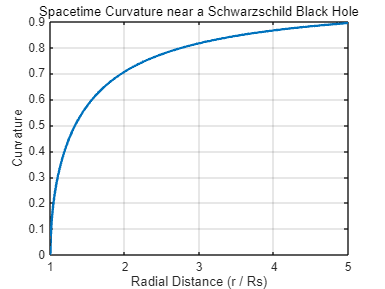

% Schwarzschild Black Hole Event Horizon Visualization

% Define constants
G = 6.67430e-11;  % Gravitational constant (m^3 kg^-1 s^-2)
M = 1.989e30;     % Mass of black hole (e.g., mass of the sun in kg)
c = 3e8;          % Speed of light (m/s)
Rs = 2 * G * M / c^2;  % Schwarzschild radius (event horizon)

% Define radial distance
r = linspace(Rs, 5*Rs, 500);

% Define spacetime curvature around the black hole
curvature = sqrt(1 - Rs ./ r);

% Plot the spacetime curvature
figure;
plot(r / Rs, curvature, 'LineWidth', 2);
xlabel('Radial Distance (r / Rs)');
ylabel('Curvature');
title('Spacetime Curvature near a Schwarzschild Black Hole');
grid on;

슈바르츠실트 반지름을 기준으로 블랙홀의 중력장이 어떻게 형성되고, 이벤트 지평선 내에서 어떤 물질이나 빛도 빠져나올 수 없다는 것을 시각화할 수 있습니다.

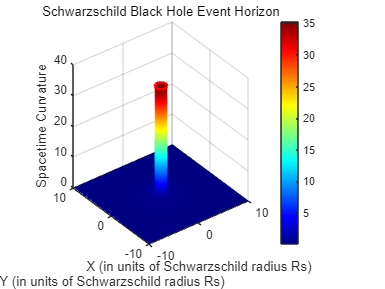

% Schwarzschild Black Hole Event Horizon Visualization in MATLAB

% Constants
G = 6.67430e-11;  % Gravitational constant (m^3 kg^-1 s^-2)
M = 1.989e30;     % Mass of the black hole (e.g., mass of the sun in kg)
c = 3e8;          % Speed of light (m/s)

% Calculate Schwarzschild radius
Rs = 2 * G * M / c^2;  % Schwarzschild radius (event horizon)

% Define grid for space coordinates (2D slice)
[x, y] = meshgrid(linspace(-10 * Rs, 10 * Rs, 500), linspace(-10 * Rs, 10 * Rs, 500));

% Calculate radial distance from the center
R = sqrt(x.^2 + y.^2);

% Event horizon: curvature becomes infinite as R approaches Rs
% Simplified curvature model (1/R term for distance, set max curvature at event horizon)
curvature = Rs ./ (R + 1e-3);  % Add a small value to avoid division by zero at the center

% Limit the curvature inside the event horizon
curvature(R <= Rs) = max(curvature(:));

% Create a 3D surface plot of the spacetime curvature
figure;
surf(x / Rs, y / Rs, curvature, 'EdgeColor', 'none');
xlabel('X (in units of Schwarzschild radius Rs)');
ylabel('Y (in units of Schwarzschild radius Rs)');
zlabel('Spacetime Curvature');
title('Schwarzschild Black Hole Event Horizon');
colormap('jet');
shading interp;
colorbar;
grid on;

% Highlight the event horizon as a circle
hold on;
theta = linspace(0, 2*pi, 100);
plot3(Rs/Rs * cos(theta), Rs/Rs * sin(theta), max(curvature(:)) * ones(size(theta)), 'r', 'LineWidth', 2);
hold off;

**상수 정의**:

- $G$: 중력 상수, $M$: 블랙홀의 질량 (예: 태양 질량), $c$: 빛의 속도.

- 블랙홀의 질량을 태양 질량으로 가정하여 이벤트 지평선을 계산합니다.

- **슈바르츠실트 반지름 계산**:

- 블랙홀의 질량에 따라 슈바르츠실트 반지름 $R_s$�를 계산합니다. 이 반지름이 이벤트 지평선을 정의하는 경계입니다.

- **2D 공간 좌표계 설정**:

- $x$와 $y$ 좌표계를 설정하여 블랙홀 주변의 공간을 표현합니다. 공간의 크기는 이벤트 지평선 $R_s$�의 10배로 설정하여, 블랙홀 주변의 시공간 휘어짐을 넓은 범위에서 볼 수 있게 합니다.

**곡률 계산**:

- 슈바르츠실트 반지름 $R_s$�에 따라 곡률을 계산합니다. 중심에 가까울수록 곡률이 더 커지며, $R_s$내부에서는 곡률이 최대값으로 고정됩니다.

- 이 값은 시공간이 블랙홀의 이벤트 지평선 내부에서 극도로 휘어진 상태를 나타냅니다.

**설명:**

- **블랙홀의 질량**이 태양 질량 정도일 때, 이벤트 지평선의 반지름은 $R_s \approx 2.95 \, \text{km}$입니다.

- 이벤트 지평선 바깥에서는 시공간이 휘어지지만, 빛이나 물질은 빠져나올 수 있습니다.

- 이벤트 지평선 안쪽에서는 빛조차도 빠져나올 수 없으며, 시공간의 휘어짐은 극도로 커집니다.

- 이 시각화는 슈바르츠실트 블랙홀 주변의 시공간이 어떻게 휘어지는지를 보여주며, 이벤트 지평선이 빨간 원으로 표시되어 경계를 나타냅니다.

- **슈바르츠실트 반지름**은 블랙홀의 중력장에서 빛이 빠져나올 수 없는 경계를 정의합니다. 이 경계 안쪽에서는 아무것도 탈출할 수 없으며, 시공간은 무한히 휘어집니다.

- 이 시각화는 블랙홀의 이벤트 지평선과 주변의 시공간 곡률을 직관적으로 이해하는 데 도움을 줍니다.

- 실제 블랙홀은 시공간을 더 복잡하게 휘어지게 만들며, 중력파나 강한 중력 렌즈 효과를 발생시킬 수 있습니다.